clc; clf
transform_scan_global(0,0,1,0)

transform_scan_global(0.75,0.25,1,-1)

load gauntlet.mat
origins = [-0.75 0.25; 1.75 0.25; -0.75 -2.75; 1.75 -2.75];

% the orientation of the Neato relative to the Global frame in radians.
% A positive angle here means the Neato's ihat_N axis was rotated
% counterclockwise from the ihat_G axis.
orientations = [-pi/4 -3*pi/4 pi/4 3*pi/4];
a = origins(2,1);
b = origins(2,2);
c = -1;
d = -1;
T_1 = [1 0 -0.084; 0 1 0; 0 0 1];
r = r_all(:,1)

r = 360×1 single column vector
    2.9115
    2.9637
    3.0187
    3.0767
    3.1380
    3.2028
    3.8349
    3.7823
    3.7322
    2.0187


theta = theta_all(:,1)

theta =          0
    0.0175
    0.0349
    0.0524
    0.0698
    0.0873
    0.1047
    0.1222
    0.1396
    0.1571


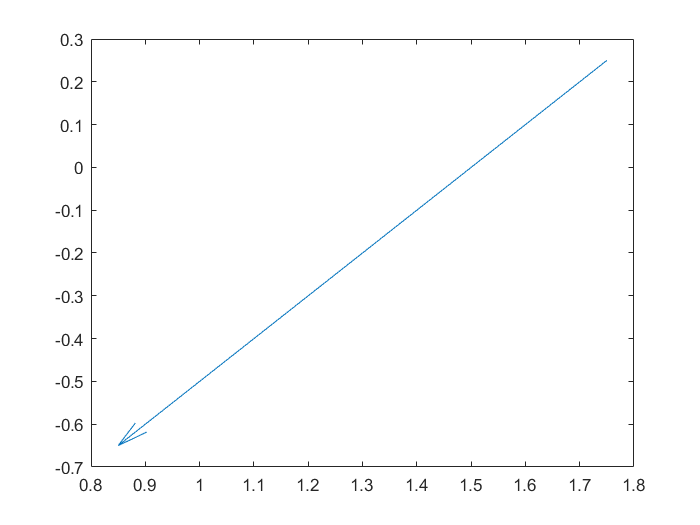

theta_initial = atan(d/c);
coords = [r.*cos(theta),r.*sin(theta)]';
    quiver(a,b,c,d);

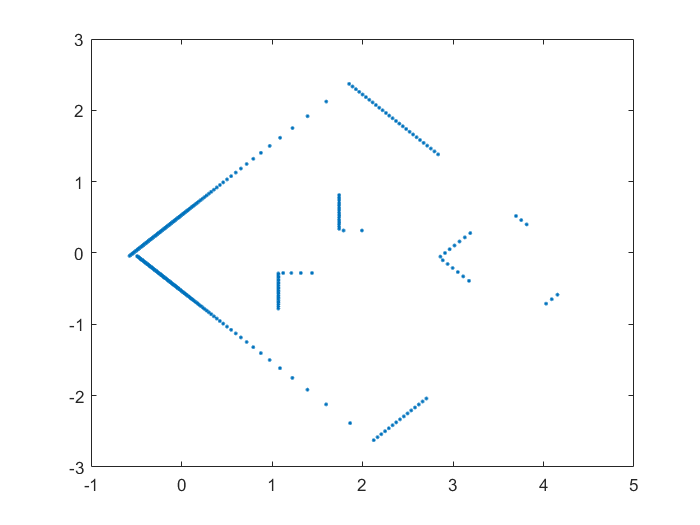

    plot(coords(1,:),coords(2,:),'.');

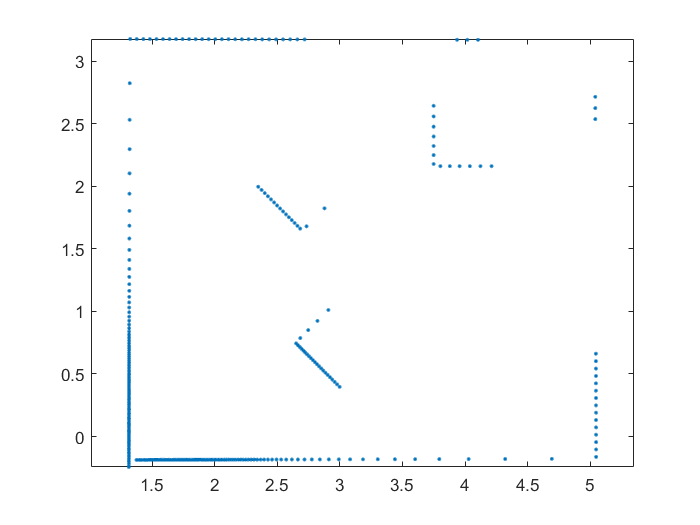

%     polarplot(-theta_1,-r_1,'*');
%     plot(x, y, "*")

    % vector test
    % R = [1,0];
    % r = [x,y];
    % resultant_vec = R + r;

    % matrices
    R = [cos(theta_initial) -sin(theta_initial) 0; sin(theta_initial) cos(theta_initial) 0; 0 0 1];
    T = [1 0 a; 0 1 b; 0 0 1];

    for point = 1:360
        r = [coords(1,point); coords(2,point); 1];
        r_n = T_1 * r;
        %plot(r_n(1,:),r_n(2,:));
        r_g = T * R * r_n;
        %plot(r_g(1,:),r_g(2,:));
        r_g_total(:,point) = r_g(:, 1);
    end 
    plot(r_g_total(1,:),r_g_total(2,:),'.');
    axis equal 